close all; clear; clc;

# STv2 transiant response

**file name**: STv2_TM15d_20180824.mlx

**keywords:** 

**date of test:** 20180824

**file created by:** 20180830, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
%p = 0.00228519349876825;                  %[slugs/ft^3]
p = 0.002377;
% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('STv2_TM15d.mat');
time = STv2_TM15d(:,1);                       % [sec]
PWM = STv2_TM15d(:,2);                        % [micro sec]
Q = STv2_TM15d(:,4);                          % [ft.lbf]
T = STv2_TM15d(:,5);                          % [lbf]
Input_V = STv2_TM15d(:,6);                    % [Volts]
Input_A = STv2_TM15d(:,7);                    % [Amps]
rot_speed_rpm = STv2_TM15d(:,8);              % [RPM]
% convert to rad for calculation purposes
rot_speed_rad = rot_speed_rpm .* (pi/30);   % [rad/sec]
P_in_W = STv2_TM15d(:,9);                     % [Watts]
P_out_W = STv2_TM15d(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = STv2_TM15d(:,11);                 % [%]
Prop_Eff = STv2_TM15d(:,12);                  % [lbf/Watts]
Overall_Eff = STv2_TM15d(:,13);               % [lbf/Watts]  
ESC_Temp = STv2_TM15d(:,14);                  % [F]
Motor_Temp = STv2_TM15d(:,15);                % [F]

disk_loading = T ./ area;                     % [lb/sq.ft]

**Settling Time and Max acceleration**

Settling_time = STv2_TM15d(:,17); % [s]
Max_Acc = STv2_TM15d(:,18);      % [RPM]


## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

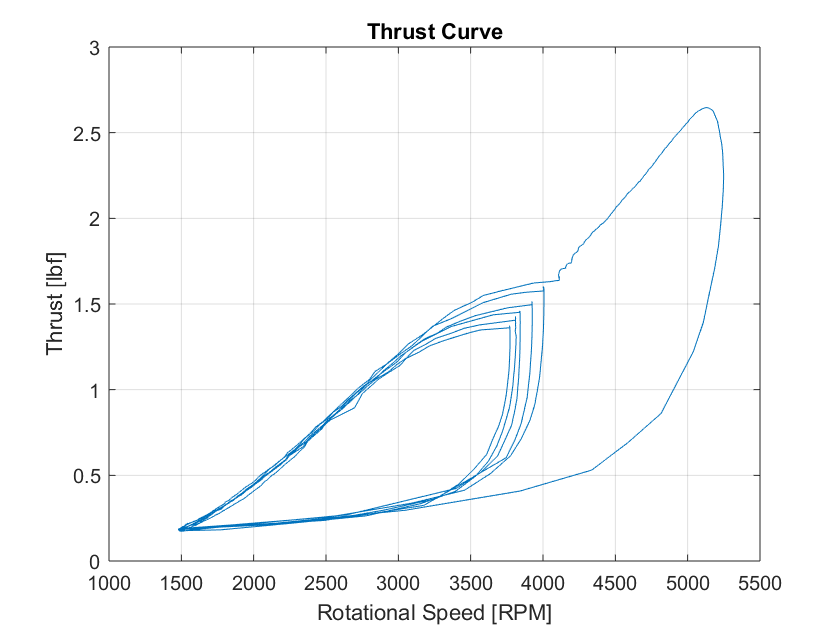

figure(1)
plot(rot_speed_rpm(157:5171), T(157:5171)); title('Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');

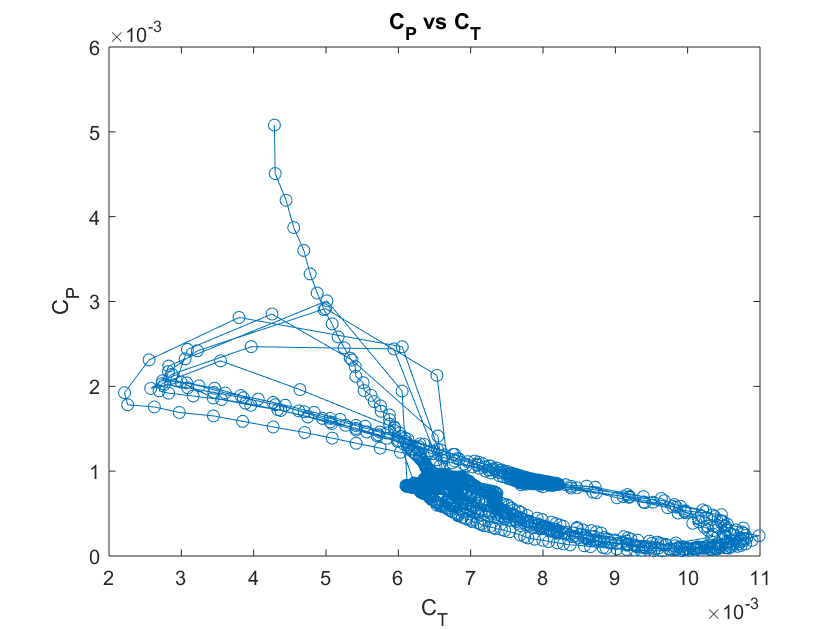


figure(2)
plot(C_T(30:5171), C_P(30:5171),'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

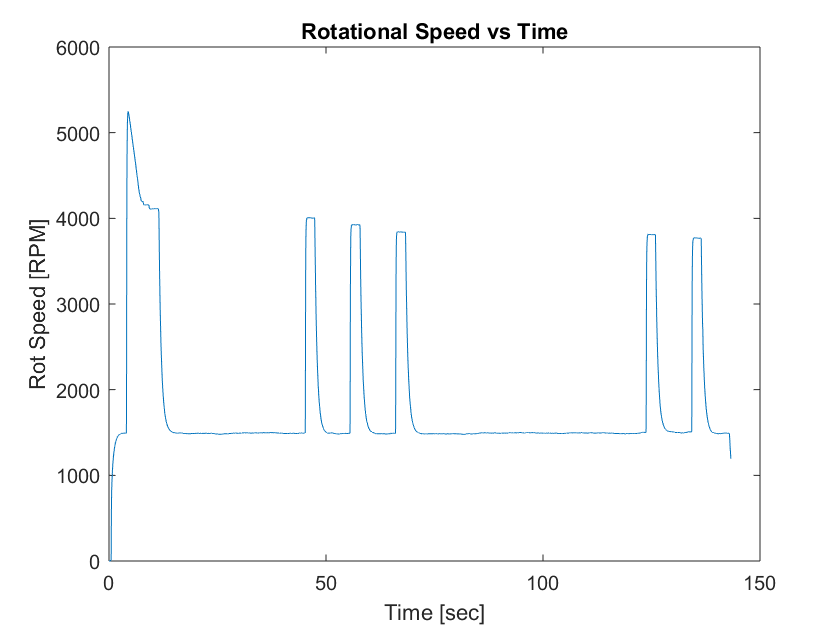


figure(3)
plot(time, rot_speed_rpm); title('Rotational Speed vs Time'); 
xlabel('Time [sec]'); ylabel('Rot Speed [RPM]')

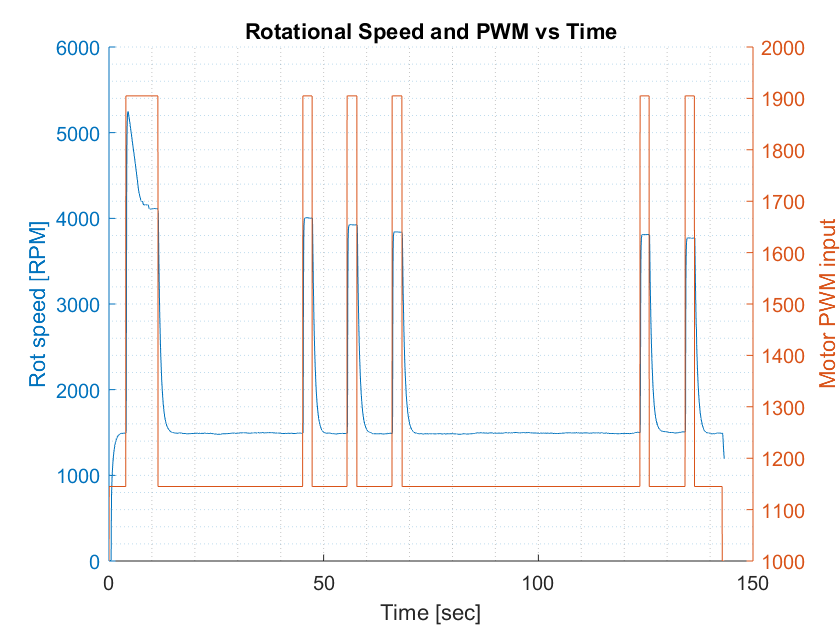


figure(4)
hold on
yyaxis left
plot(time, rot_speed_rpm);
ylabel('Rot speed [RPM]');
yyaxis right
plot(time, PWM);
ylabel('Motor PWM input');
title('Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

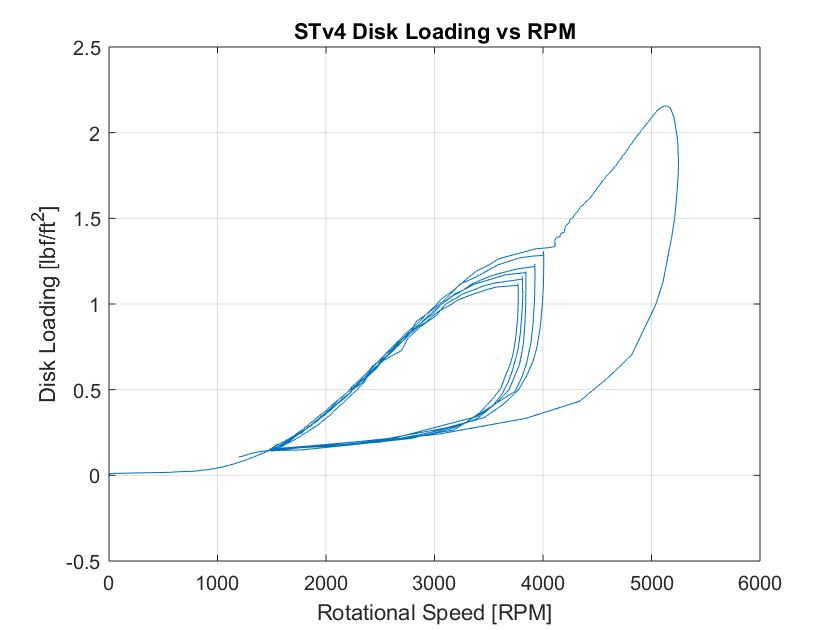


figure(5)
plot(rot_speed_rpm, disk_loading); title('STv4 Disk Loading vs RPM');
xlabel('Rotational Speed [RPM]'); ylabel('Disk Loading [lbf/ft^2]')
grid('on');

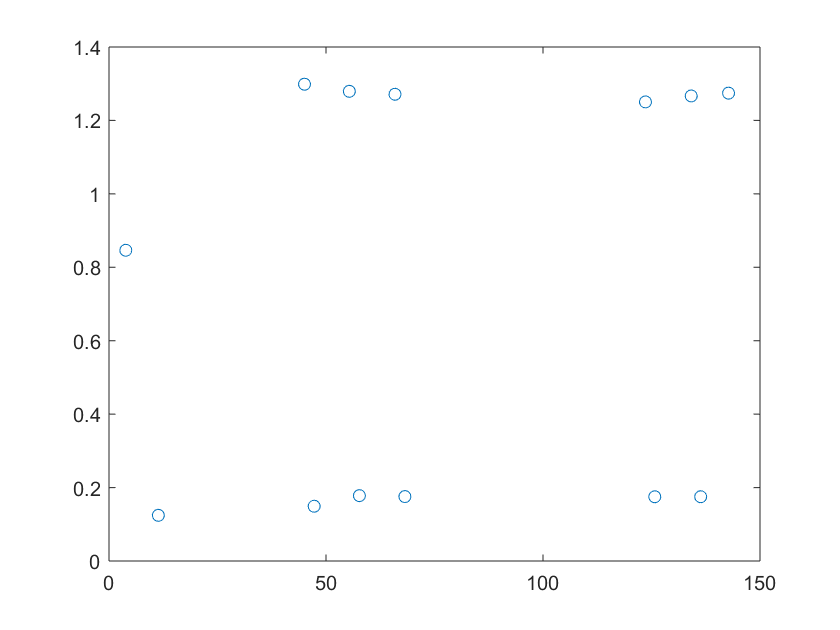


figure(6)
plot(time, Settling_time, 'o-');

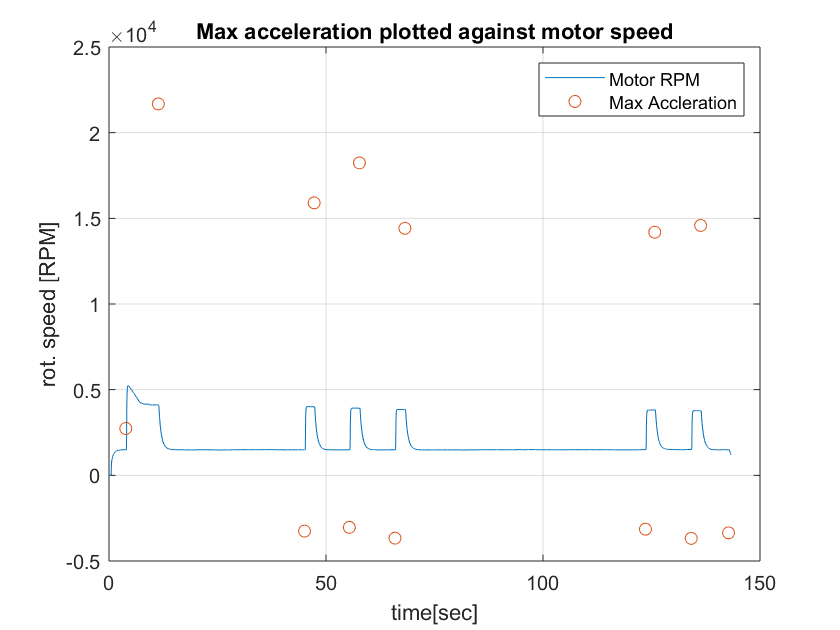


figure(7)
plot(time, rot_speed_rpm, time, Max_Acc, 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 
legend('Motor RPM', 'Max Accleration'); grid('on');

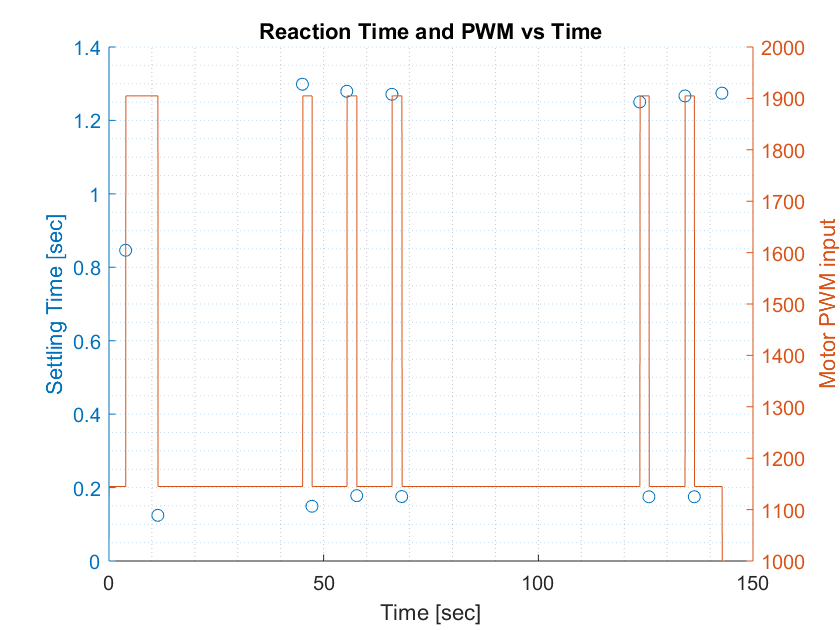


figure(8)
hold on
yyaxis left
plot(time,Settling_time, 'o-');
ylabel('Settling Time [sec]');
yyaxis right
plot(time, PWM);
ylabel('Motor PWM input');
title('Reaction Time and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

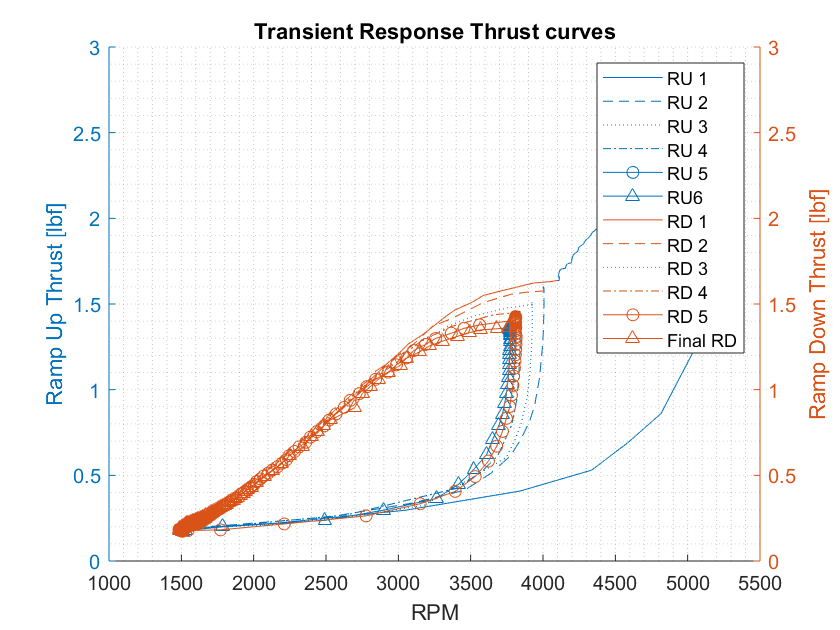


figure(9)
hold on
yyaxis left
% ramp up
plot(rot_speed_rpm(157:447), T(157:447));
plot(rot_speed_rpm(1636:1715), T(1636:1715));
plot(rot_speed_rpm(1977:2050), T(1977:2050));
plot(rot_speed_rpm(2320:2393), T(2320:2393));
plot(rot_speed_rpm(4451:4533), T(4451:4533));
plot(rot_speed_rpm(4853:4933), T(4853:4933));

legend('RU 1', 'RU 2', 'RU 3', 'RU 4', 'RU 5', 'RU6'); 
ylim([0 3]);
ylabel('Ramp Up Thrust [lbf]');

yyaxis right
%ramp down - disregarding the initial 145 setting points (before the first ramp up)
plot(rot_speed_rpm(447:1635), T(447:1635), 'DisplayName', 'RD 1');
plot(rot_speed_rpm(1715:1976), T(1715:1976), 'DisplayName', 'RD 2');
plot(rot_speed_rpm(2050:2319), T(2050:2319), 'DisplayName', 'RD 3');
plot(rot_speed_rpm(2393:4450), T(2393:4450), 'DisplayName', 'RD 4');
plot(rot_speed_rpm(3533:4852), T(3533:4852), 'DisplayName', 'RD 5');
plot(rot_speed_rpm(4933:5171), T(4933:5171), 'DisplayName', 'Final RD');
ylabel('Ramp Down Thrust [lbf]');
ylim([0 3]);

title('Transient Response Thrust curves');
xlabel('RPM');
grid('minor');
hold off

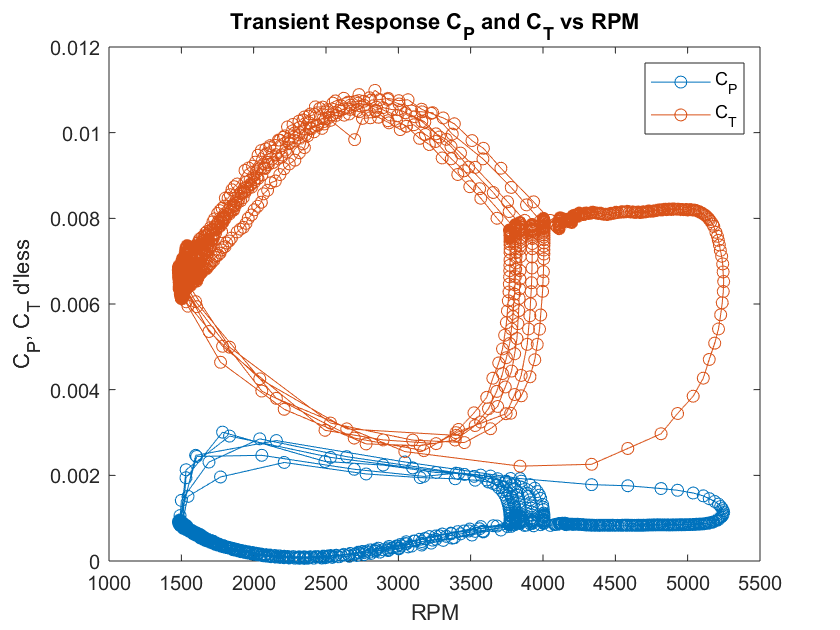


figure(10)
plot(rot_speed_rpm(157:5171), C_P(157:5171), 'o-', rot_speed_rpm(157:5171), C_T(157:5171), 'o-');
title('Transient Response C_P and C_T vs RPM'); legend('C_P', 'C_T');
xlabel('RPM'); ylabel("C_P, C_T d'less")

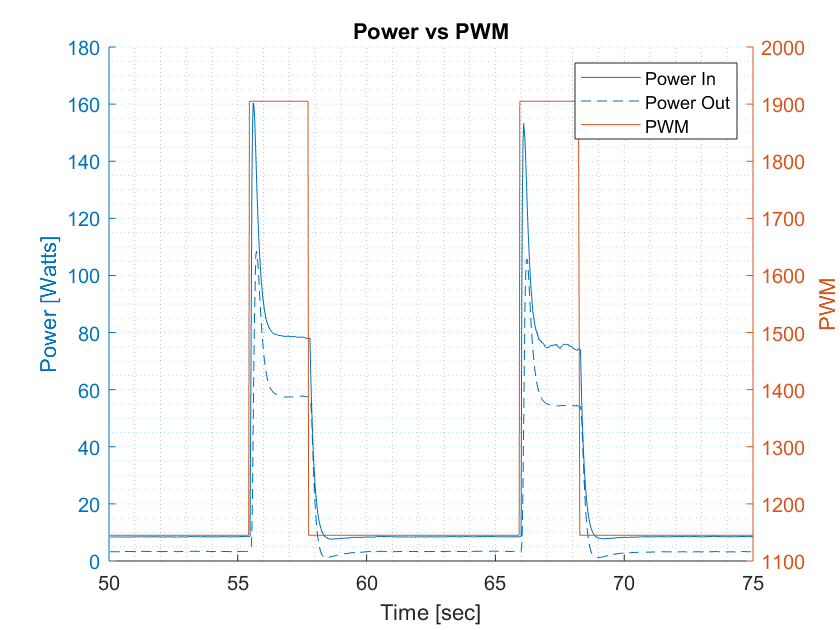




figure(11)
hold on
yyaxis left
plot(time(1808:2813),P_in_W(1808:2813), time(1808:2813), P_out_W(1808:2813));
ylabel('Power [Watts]');
legend('Power In', 'Power Out')
yyaxis right
plot(time(1808:2813), PWM(1808:2813), 'DisplayName','PWM');
ylabel('PWM');
title('Power vs PWM');
xlabel('Time [sec]');
xlim([50 75]);
grid('minor');
hold off

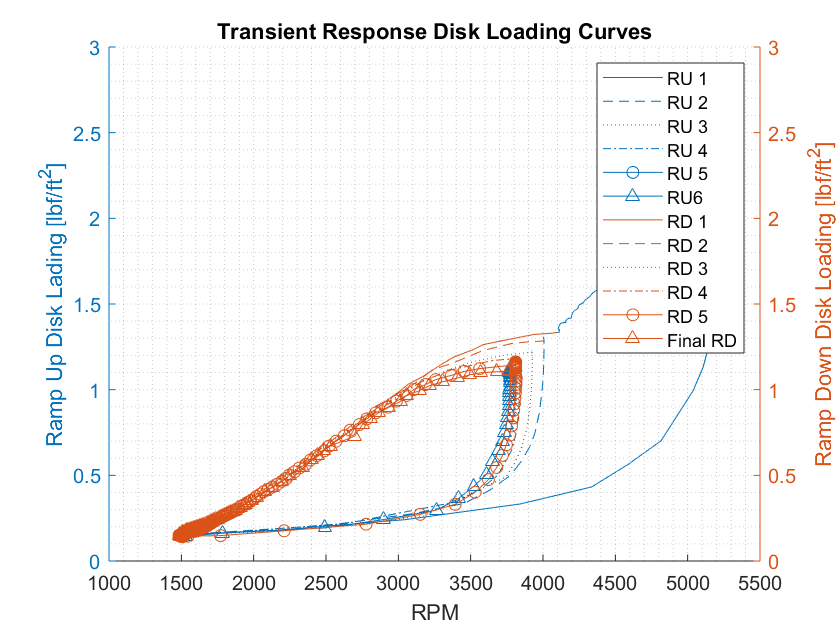




figure(12)
hold on
yyaxis left
% ramp up
plot(rot_speed_rpm(157:447), disk_loading(157:447));
plot(rot_speed_rpm(1636:1715), disk_loading(1636:1715));
plot(rot_speed_rpm(1977:2050), disk_loading(1977:2050));
plot(rot_speed_rpm(2320:2393), disk_loading(2320:2393));
plot(rot_speed_rpm(4451:4533), disk_loading(4451:4533));
plot(rot_speed_rpm(4853:4933), disk_loading(4853:4933));

legend('RU 1', 'RU 2', 'RU 3', 'RU 4', 'RU 5', 'RU6'); 
ylim([0 3]);
ylabel('Ramp Up Disk Lading [lbf/ft^2]');

yyaxis right
%ramp down - disregarding the initial 145 setting points (before the first ramp up)
plot(rot_speed_rpm(447:1635), disk_loading(447:1635), 'DisplayName', 'RD 1');
plot(rot_speed_rpm(1715:1976), disk_loading(1715:1976), 'DisplayName', 'RD 2');
plot(rot_speed_rpm(2050:2319), disk_loading(2050:2319), 'DisplayName', 'RD 3');
plot(rot_speed_rpm(2393:4450), disk_loading(2393:4450), 'DisplayName', 'RD 4');
plot(rot_speed_rpm(3533:4852), disk_loading(3533:4852), 'DisplayName', 'RD 5');
plot(rot_speed_rpm(4933:5171), disk_loading(4933:5171), 'DisplayName', 'Final RD');
ylabel('Ramp Down Disk Loading [lbf/ft^2]');
ylim([0 3]);

title('Transient Response Disk Loading Curves');
xlabel('RPM');
grid('minor');

hold off

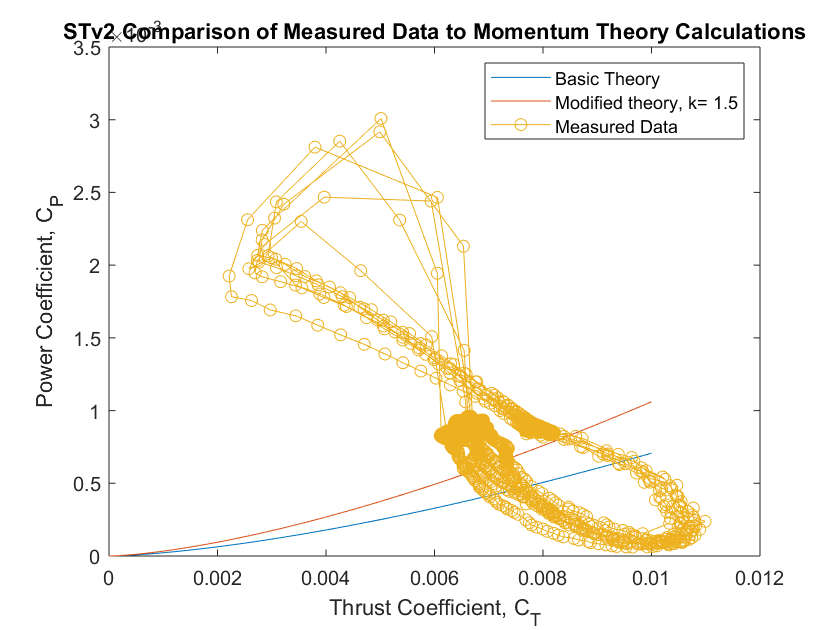

k = 1.5;
C_T_theory = linspace(0, 0.01, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(13)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi, C_T(157:5171), C_P(157:5171), 'o-');
title('STv2 Comparison of Measured Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.5', 'Measured Data');